clear 
len = 16;
function total_gain = production_decision(x)

row_p = [0.10
    0.10
    0.10
    0.10
    0.10
    0.10
    0.10
    0.10];%传递给下一个流程的零件次品率

% row_p_factory = row_p;%留存在仓库里的零件次品率
row_pay = [2.00
    8.00
    12.00
    2.00
    8.00
    12.00
    8.00
    12.00];

num_parts = 1e4 * ones(8,1);
row_detection_cost = [1.00
    1.00
    2.00
    1.00
    1.00
    2.00
    1.00
    2.00];
semi_p = [
    0.10
    0.10
    0.10];%传递给下一个流程的半成品次品率
% semi_p_factory = semi_p;%留在仓库里的半成品次品率
semi_pay = [
    8.00
    8.00
    8.00];
semi_detection_cost = [
    4.00
    4.00
    4.00];
disassemble = [
    6.00
    6.00
    6.00 ];
p_final = 0.1;
p3 = 0.1;
pay_final = 8;
detection_cost_final = 6;
disassemble_final = 10;

gain = 200;
replace = 40;

detect_parts = x(1:8);%是否检测零件
detect_semi = x(9:11);%是否检测半成品
IsDisassemble_semi = x(12:14);%是否拆解半成品
detect_final = x(15);%是否检测成品
IsDisassemble_final = x(16);%是否拆解成品
for i = 1:3
    if detect_semi(i) == 0 && IsDisassemble_semi(i) == 1
        total_gain = 0;
        return
    end
end
% if x == ones(16,1)
%     total_gain = 0;
%     return
% end
flag = ones(8,1);
% temp_flag = ones(3,1);
unparts = zeros(8,1);%废器原材料
unsemis = zeros(3,1);
num_temp_products = zeros(3,1);

%计算半成品次品率
% semi_p(1) = get_p3(x(1:3));
% semi_p(2) = get_p3(x(4:6));
% semi_p(3) = get_p2(x(7:8));

%计算成品次品率
% p_final = cal_p3(detect_semi,semi_p,p_final);

%%%
row_detection_cost = 90*row_detection_cost.\row_pay;
% row_pay = 10 * row_pay./row_detection_cost;
% 
% disassemble = disassemble./semi_pay;
% semi_detection_cost = semi_detection_cost./semi_pay;
% semi_pay = semi_pay./semi_pay;
% 
% detection_cost_final = detection_cost_final/pay_final;
% disassemble_final = disassemble_final/pay_final;
% pay_final = pay_final/pay_final;
% 
% gain = 25;
% replace = 5;
%%%

total_cost = sum(row_pay.*num_parts);
total_gain = 0;
while 1
    %检测原材料1--8
    for i = 1:8
        if detect_parts(i)
            total_cost = total_cost + num_parts(i)*row_detection_cost(i);
            if flag(i)
                unparts(i) = binornd(num_parts(i),row_p(i));
                % unparts(i) = num_parts(i)*row_p(i);

                num_parts(i) = num_parts(i) - unparts(i);
                unparts(i) = 0;%废弃零部件
            end
            % row_p_factory(i) = ((num_parts(i)+unparts(i))*row_p_factory(i) - unparts(i))/num_parts(i);
            row_p(i) = 0;
            
            flag(i) = 0;
        end
    end
    
    % num_parts
    %装配 半成品一到三
    num_temp_products(1) = min(num_parts(1:3));
    num_parts(1:3) = num_parts(1:3) - ones(3,1)*num_temp_products(1);
    %装配半成品1时，由于有新零件的加入，半成品1的次品率需要更新
    semi_p(1) = cal_p3(detect_parts(1:3),row_p(1:3),semi_p(1));

    num_temp_products(2) = min(num_parts(4:6));
    num_parts(4:6) = num_parts(4:6) - ones(3,1)*num_temp_products(2);
    semi_p(2) = cal_p3(detect_parts(4:6),row_p(4:6),semi_p(2));

    num_temp_products(3) = min(num_parts(7:8));
    num_parts(7:8) = num_parts(7:8) - ones(2,1)*num_temp_products(3);
    semi_p(3) = cal_p(detect_parts(7),detect_parts(8),row_p(7),row_p(8),semi_p(3));

    total_cost = total_cost + num_temp_products'*semi_pay;

    %检测半成品
    for i = 1:3
        if detect_semi(i)
            % if temp_flag(i)
                unsemis(i) = binornd(num_temp_products(i),semi_p(i));
                % unsemis(i) = num_temp_products(i)*semi_p(i);
                num_temp_products(i) = num_temp_products(i) - unsemis(i);
            % end
            %需要计算出，次品的次品率。
            temp_p(i) = semi_p(i);
            semi_p(i) = 0;
        else
            temp_p(i) = semi_p(i);
            % temp_flag(i) = 0;
        end
        % if i == 1
        %     row_p(1:3) = 0;
        % elseif i ==2
        %     row_p(4:6) = 0;
        % else
        %     row_p(7:8) = 0;
        % end

    end
    total_cost = total_cost + semi_detection_cost(1)*(detect_semi' * num_temp_products);
    
    
    
    %装配成品

    num_products = min(num_temp_products);
    num_temp_products = num_temp_products - ones(3,1) * num_products;
    p_final = cal_p3(detect_semi,semi_p,p3);
    total_cost = total_cost + num_products*pay_final;
    
    %检测成品
    if detect_final

        defective_products = binornd(num_products, p_final);
        % defective_products = num_products* p_final;
        %total_cost = total_cost + defective_products * detection_cost_final;
        total_cost = total_cost + num_products * detection_cost_final;
        unproducts = defective_products;
        num_products = num_products - defective_products;%合格的产品数

    else
        %不检测成品，则直接售出
        % disqualify_poducts = binornd(num_products, p_final);
        disqualify_poducts = num_products* p_final;
        replacement_cost = replace * disqualify_poducts;
        unproducts = disqualify_poducts;
        % total_cost = total_cost + disqualify_poducts * gain + replacement_cost;
        total_cost = total_cost  + replacement_cost;
        num_products = num_products - disqualify_poducts;
    end
    if isnan(num_products)
        disp("isnan(num_products")
        break
    end
    total_gain = total_gain + num_products * gain;
    
    
    
    % p_final = 0;
    % if IsDisassemble_final%是否拆解成品
    % 
    %     total_cost = total_cost + unproducts * disassemble_final;
    %     % p1 = num_parts1/(num_parts1 + unproducts)*p1 + unproducts/(num_parts1 + unproducts) * p1/p_final;
    %     for i = 1:3
    %         % if detect_final
    %         %     semi_p(i) = num_temp_products(i) * semi_p(i)/(num_temp_products(i)+unproducts);
    %         % else
    %         % semi_p
    %         % num_temp_products
    % 
    %         semi_p(i) = num_temp_products(i)/(num_temp_products(i)+unproducts)*semi_p(i) + unproducts/(num_temp_products(i) + unproducts) * semi_p(i)/p_final;%
    % 
    %         % end
    %     end
    % 
    %     num_temp_products = num_temp_products + ones(3,1)*unproducts;
    % end

    if IsDisassemble_final%是否拆解成品次品
        
        total_cost = total_cost + unproducts * disassemble_final;
        % p1 = num_parts1/(num_parts1 + unproducts)*p1 + unproducts/(num_parts1 + unproducts) * p1/p_final;
        for i = 1:3
            % if detect_final
            %     semi_p(i) = num_temp_products(i) * semi_p(i)/(num_temp_products(i)+unproducts);
            % else
            % semi_p
            % num_temp_products
            % (num_temp_products(i)+unproducts)
            semi_p(i) = num_temp_products(i)/(num_temp_products(i)+unproducts)*semi_p(i) + unproducts/(num_temp_products(i) + unproducts) * semi_p(i)/p_final;%

            % end
        end
        
        num_temp_products = num_temp_products + ones(3,1)*unproducts;
        unproducts = 0;%拆掉了就是0
    end

    %是否拆解半成品
    if IsDisassemble_semi(1)
        if detect_semi(1) 
            for i = 1:3
                %if semi_p(1) == 0
                row_p(i) = num_parts(i)/(num_parts(i)+unsemis(1)) * row_p(i) + unsemis(1)/(num_parts(i)+unsemis(1)) * row_p(i)/temp_p(1);        
            end
            % semi_p(1) = cal_p3(detect_parts(1:3),row_p(1:3),semi_p(1));%
            num_parts(1) = num_parts(1) + unsemis(1);
            num_parts(2) = num_parts(2) + unsemis(1);
            num_parts(3) = num_parts(3) + unsemis(1);
            
            total_cost = total_cost + unsemis(1)*disassemble(1);
            unsemis(1) = 0;
        end
    else
        if detect_semi(1)
            unsemis(1) = 0;
        end
    end

    if IsDisassemble_semi(2)
        if detect_semi(2)
        for i = 4:6        
            row_p(i) = num_parts(i)/(num_parts(i)+unsemis(2)) * row_p(i) + unsemis(2)/(num_parts(i)+unsemis(2)) * row_p(i)/temp_p(2);
        end
        % semi_p(2) = cal_p3(detect_parts(4:6),row_p(4:6),semi_p(2));
        num_parts(4) = num_parts(4) + unsemis(2);
        num_parts(5) = num_parts(5) + unsemis(2);
        num_parts(6) = num_parts(6) + unsemis(2);
        
        total_cost = total_cost + unsemis(2)*disassemble(2);
        unsemis(2) = 0;
        end
    else
        if detect_semi(2)
            unsemis(2) = 0;
        end
    end
    if IsDisassemble_semi(3)
        if detect_semi(3)
            for i = 7:8
                row_p(i) = num_parts(i)/(num_parts(i)+unsemis(3)) * row_p(i) + unsemis(3)/(num_parts(i)+unsemis(3)) * row_p(i)/temp_p(3);
            end
            % semi_p(3) = cal_p(detect_parts(7),detect_parts(8),row_p(7),row_p(8),semi_p(3));
            num_parts(7) = num_parts(7) + unsemis(3);
            num_parts(8) = num_parts(8) + unsemis(3);
            total_cost = total_cost + unsemis(3)*disassemble(3);
            unsemis(3) = 0;
        end
    else
        if detect_semi(3)
            unsemis(3) = 0;
        end
    end

    % p_final = cal_p3(detect_semi,semi_p,p3);

    if p_final >0.99
        disp(p_final)
        break
    end

    if any(num_parts<=0)
        break
    end
    
    if any(semi_p>1)
        
        break
    end
    if any(row_p>0.99)%如果零件次品率很大，说明几乎完好零件。
       
        break
    end
    % if any(isnan(num_parts))
    %     break
    % end
    % end
    % semi_p
    % row_p
    % temp_p
    % num_parts
    % semi_p
    % p_final
end

% total_gain = total_gain + sum(num_parts.*row_pay);

total_gain = total_gain - total_cost;

end


result = zeros(20,16);
simulate = 50

simulate = 50

hold on
colormap(jet);
x  = 1:29;
income = [simulate,1];
each_cost = [];

for i = 1:simulate
x3 = optimvar("x",len,"Type","integer","LowerBound",0,"UpperBound",1);

initialPoint2.x = zeros(size(x3));

problem = optimproblem("ObjectiveSense","Maximize");

problem.Objective = fcn2optimexpr(@production_decision,x3);
options2 = optimoptions("ga","Display","iter","UseParallel",true);

show(problem);
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint2,...
    "Solver","ga","Options",options2);
solution
reasonSolverStopped
objectiveValue
result(i,:) = solution.x
[income(i),each_cost(i,:)] = Pbl4eachCost(result(i,:)');
     % plot(x, each_cost(i,:)/1e4, 'LineWidth', 3);
end


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200        4.58e+05        6.25e+04        0
    2              300       4.622e+05       1.008e+05        0
    3              400       4.573e+05       1.173e+05        1
    4              500       4.635e+05       1.496e+05        0
    5              600       4.786e+05       1.761e+05        0
    6              700       4.926e+05       1.918e+05        0
    7              800       4.961e+05       1.814e+05        0
isnan(num_products
    8              900       4.877e+05       1.911e+05        1
    9             1000        4.89e+05       1.701e+05        0
   10             1100    

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9917e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332           1


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0



  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.705e+05        3.88e+04        0
    2              300       4.865e+05       7.682e+04        0
isnan(num_products
isnan(num_products
    3              400       4.904e+05       1.227e+05        0
    4              500       4.871e+05       1.442e+05        1
isnan(num_products
isnan(num_products
    5              600       4.905e+05       1.361e+05        0
isnan(num_products
    6              700       4.941e+05       1.517e+05        0
isnan(num_products
    7              800       4.974e+05       1.724e+05        0
isnan(num_products
isnan(num_products
    8              90

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9763e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0



  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200        4.73e+05       8.358e+04        0
isnan(num_products
isnan(num_products
    2              300       4.777e+05       9.323e+04        0
    3              400       4.854e+05       1.063e+05        0
isnan(num_products
isnan(num_products
    4              500        4.91e+05       1.405e+05        0
isnan(num_products
    5              600       4.813e+05        1.28e+05        1
isnan(num_products
    6              700       4.739e+05       1.686e+05        2
    7              800       4.842e+05       1.822e+05        0
isnan(num_products
    8              90

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9239e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.667e+05       3.816e+04        0
    2              300         4.7e+05        5.64e+04        0
    3              400       4.853e+05       8.161e+04        0
isnan(num_products
    4              500        4.84e+05       1.181e+05        1
    5              600       4.919e+05       1.333e+05        0
    6              700        4.87e+05       1.754e+05        1
    7              800       4.942e+05       1.927e+05        0
isnan(num_products
    8              900        4.97e+05       1.843e+05        0
    9             1000       4.91

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.8565e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809    58063937


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.575e+05       6.279e+04        0
    2              300       4.779e+05       9.441e+04        0
    3              400       4.657e+05       1.084e+05        1
isnan(num_products
    4              500        4.78e+05       1.351e+05        0
    5              600       4.846e+05       1.566e+05        0
    6              700       4.884e+05       1.742e+05        0
    7              800       4.825e+05       1.884e+05        1
isnan(num_products
    8              900       4.899e+05       1.669e+05        0
    9             1000       4.98

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9056e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809    58063937    56774007


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200       4.603e+05       5.196e+04        0
    2              300       4.702e+05       8.666e+04        0
    3              400        4.72e+05       1.049e+05        0
    4              500       4.735e+05       1.142e+05        0
    5              600       4.608e+05       1.448e+05        1
    6              700       4.976e+05       1.677e+05        0
    7              800       4.979e+05       1.886e+05        0
isnan(num_products
isnan(num_products
    8              900       4.853e+05       1.899e+05        1
    9             1000       4.937e+05       1.794e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9936e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.571e+05        6.51e+04        0
isnan(num_products
    2              300        4.67e+05        9.36e+04        0
    3              400       4.689e+05       9.856e+04        0
    4              500       4.636e+05       1.277e+05        1
    5              600       4.546e+05       1.166e+05        2
    6              700       4.651e+05       1.366e+05        0
    7              800       4.651e+05        1.52e+05        0
isnan(num_products
    8              900       4.655e+05       1.594e+05        0
    9             1000       4.892e+05       1.716e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9275e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.676e+05       5.811e+04        0
isnan(num_products
isnan(num_products
    2              300       4.654e+05       8.437e+04        1
    3              400       4.746e+05        1.21e+05        0
    4              500       4.979e+05       1.516e+05        0
    5              600        4.93e+05       1.577e+05        1
    6              700       4.969e+05       1.834e+05        0
isnan(num_products
    7              800       5.007e+05       1.785e+05        0
    8              900        4.93e+05       1.886e+05        1
    9             1000       5.009e+05        1.79e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9982e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200       4.686e+05       5.112e+04        0
    2              300       4.635e+05       7.808e+04        1
    3              400       4.934e+05       1.053e+05        0
    4              500       4.887e+05        1.31e+05        1
    5              600       4.897e+05       1.408e+05        0
isnan(num_products
    6              700       4.882e+05       1.466e+05        1
isnan(num_products
    7              800        4.86e+05       1.642e+05        2
isnan(num_products
    8              900       4.938e+05       1.525e+05        0
    9             1000       4.99

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9416e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.631e+05       7.416e+04        0
    2              300       4.729e+05       1.307e+05        0
isnan(num_products
isnan(num_products
    3              400       4.757e+05        1.59e+05        0
    4              500       4.756e+05       1.617e+05        1
    5              600       4.907e+05       1.903e+05        0
    6              700       4.852e+05       2.091e+05        1
isnan(num_products
    7              800       4.903e+05       2.204e+05        0
isnan(num_products
    8              900       4.901e+05       1.761e+05        1
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9785e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200       4.697e+05       4.657e+04        0
    2              300       4.749e+05       9.429e+04        0
    3              400       4.894e+05        1.01e+05        0
    4              500        4.77e+05       1.326e+05        1
    5              600       4.792e+05       1.555e+05        0
    6              700       4.693e+05       1.673e+05        1
    7              800        4.79e+05       1.669e+05        0
isnan(num_products
isnan(num_products
    8              900       4.948e+05       1.723e+05        0
    9             1000        4.96e+05       1.987e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9466e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
isnan(num_products
    1              200       4.808e+05        3.95e+04        0
isnan(num_products
    2              300       4.682e+05       6.026e+04        1
isnan(num_products
    3              400       4.695e+05       8.136e+04        0
    4              500       4.629e+05       1.133e+05        1
isnan(num_products
isnan(num_products
    5              600       4.663e+05       1.208e+05        0
isnan(num_products
    6              700       4.647e+05       1.443e+05        1
    7              800       4.694e+05       1.634e+05        0
isnan(num_products
  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9022e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200         4.5e+05       2.142e+04        0
    2              300       4.809e+05       7.779e+04        0
isnan(num_products
    3              400        4.66e+05       9.933e+04        1
    4              500        4.62e+05       1.087e+05        2
    5              600       4.884e+05       1.581e+05        0
isnan(num_products
isnan(num_products
    6              700       4.973e+05       1.667e+05        0
    7              800       4.953e+05       1.761e+05        1
isnan(num_products
isnan(num_products
    8              900       4.924e+05       1.572e+05     

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9890e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.527e+05       2.718e+04        0
    2              300       4.625e+05       5.743e+04        0
isnan(num_products
    3              400       4.766e+05        1.02e+05        0
isnan(num_products
    4              500        4.77e+05       1.351e+05        0
    5              600       4.764e+05       1.403e+05        1
    6              700       4.672e+05       1.739e+05        2
    7              800       4.657e+05        1.59e+05        3
isnan(num_products
    8              900       4.661e+05       1.718e+05        0
    9             1000       4.641e+05       1.657e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9677e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.731e+05        7.83e+04        0
    2              300       4.624e+05       1.215e+05        1
    3              400       4.654e+05       1.477e+05        0
    4              500       4.716e+05       1.555e+05        0
    5              600       4.593e+05       1.702e+05        1
isnan(num_products
    6              700       4.568e+05       1.849e+05        2
    7              800       4.558e+05       1.817e+05        3
isnan(num_products
    8              900       4.706e+05        1.79e+05        0
    9             1000       4.739e+05       1.853e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9364e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.764e+05       6.527e+04        0
    2              300       4.874e+05       8.156e+04        0
    3              400       4.806e+05       1.122e+05        1
    4              500       4.761e+05       1.348e+05        2
    5              600       4.717e+05       1.492e+05        3
    6              700       4.848e+05       1.828e+05        0
    7              800       4.812e+05       1.748e+05        1
isnan(num_products
    8              900        4.79e+05       1.565e+05        2
    9             1000       4.793e+05       1.714e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9806e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171


each_cost =      2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968           0  


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.676e+05       7.562e+04        0
isnan(num_products
    2              300       4.842e+05        1.14e+05        0
    3              400       4.775e+05       1.289e+05        1
    4              500       4.922e+05       1.024e+05        0
    5              600       4.809e+05       1.589e+05        1
    6              700       4.903e+05        1.53e+05        0
    7              800       4.959e+05       1.662e+05        0
isnan(num_products
    8              900        5.01e+05       1.683e+05        0
    9             1000       4.991e+05       1.652e+05        1
isnan(n

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9358e+05

result =      1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income =     58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160


each_cost = 17×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200        4.79e+05       5.059e+04        0
    2              300       4.548e+05        8.61e+04        1
    3              400       4.732e+05       1.246e+05        0
isnan(num_products
    4              500       4.592e+05       1.385e+05        1
    5              600       4.766e+05       1.581e+05        0
isnan(num_products
    6              700       4.893e+05        2.01e+05        0
    7              800        4.81e+05       1.981e+05        1
isnan(num_products
isnan(num_products
    8              900       4.898e+05       1.613e+05        0
isnan(num_products
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.8760e+05

result = 20×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×18
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882


each_cost = 18×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.951e+05       6.674e+04        0
    2              300       4.928e+05       8.991e+04        1
    3              400       4.996e+05       1.411e+05        0
    4              500        4.86e+05        1.54e+05        1
    5              600       4.924e+05        1.57e+05        0
    6              700       4.975e+05       1.919e+05        0
isnan(num_products
    7              800       4.998e+05       1.939e+05        0
    8              900       4.961e+05       1.756e+05        1
    9             1000       4.975e+05       1.716e+05        0
   10             1100    

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.8780e+05

result = 20×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×19
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416


each_cost = 19×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.713e+05       5.782e+04        0
    2              300       4.828e+05        1.08e+05        0
    3              400       4.675e+05       1.062e+05        1
isnan(num_products
    4              500       4.574e+05       1.145e+05        2
isnan(num_products
    5              600       4.645e+05       1.073e+05        0
    6              700       4.744e+05       1.584e+05        0
isnan(num_products
    7              800       4.653e+05       1.525e+05        1
isnan(num_products
isnan(num_products
    8              900       4.985e+05       1.725e+05        0
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0172e+05

result = 20×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×20
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895


each_cost = 20×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.789e+05       4.656e+04        0
isnan(num_products
    2              300       4.733e+05       8.972e+04        1
isnan(num_products
    3              400       4.758e+05       3.036e+04        0
isnan(num_products
    4              500       4.725e+05       9.804e+04        1
    5              600       4.731e+05       1.349e+05        0
    6              700       4.605e+05       1.567e+05        1
    7              800       4.768e+05       1.858e+05        0
isnan(num_products
    8              900       4.779e+05       1.979e+05        0
    9             1000       4.67

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0006e+05

result = 21×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×21
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221


each_cost = 21×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
isnan(num_products
    1              200       4.751e+05       7.996e+04        0
isnan(num_products
    2              300        4.85e+05        1.17e+05        0
    3              400       4.851e+05       1.331e+05        0
isnan(num_products
    4              500       4.844e+05       1.378e+05        1
    5              600       4.865e+05       1.483e+05        0
    6              700       4.829e+05       1.796e+05        1
    7              800       4.896e+05       1.779e+05        0
isnan(num_products
    8              900       4.854e+05       1.785e+05        1
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9336e+05

result = 22×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×22
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770


each_cost = 22×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.711e+05       6.959e+04        0
    2              300       4.741e+05       1.123e+05        0
isnan(num_products
    3              400       4.635e+05       1.452e+05        1
    4              500       4.796e+05       1.804e+05        0
isnan(num_products
    5              600       4.815e+05       2.018e+05        0
    6              700        4.87e+05        1.97e+05        0
    7              800       4.936e+05       1.977e+05        0
isnan(num_products
    8              900       4.876e+05        1.93e+05        1
    9             1000       4.919e+05       2.077e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0120e+05

result = 23×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×23
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510


each_cost = 23×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199       4.558e+05       2.915e+04        0
    2              299       4.765e+05       8.333e+04        0
    3              399       4.568e+05       1.318e+05        1
    4              499       4.648e+05       1.503e+05        0
    5              599       4.582e+05       1.527e+05        1
    6              699       4.663e+05       1.905e+05        0
    7              799       4.997e+05       1.971e+05        0
isnan(num_products
    8              899       4.958e+05       2.154e+05        1
    9              999       5.025e+05       2.121e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9519e+05

result = 24×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×24
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125


each_cost = 24×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.729e+05       4.867e+04        0
    2              300       4.767e+05       1.026e+05        0
isnan(num_products
    3              400       4.766e+05       1.245e+05        1
    4              500        4.98e+05       1.399e+05        0
    5              600       5.024e+05       1.586e+05        0
    6              700       4.926e+05       1.647e+05        1
isnan(num_products
isnan(num_products
    7              800       5.014e+05       1.449e+05        0
    8              900       5.013e+05       1.603e+05        1
    9             1000       4.98

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9447e+05

result = 25×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×25
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697


each_cost = 25×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.751e+05       6.033e+04        0
    2              300       4.682e+05       7.862e+04        1
    3              400       4.697e+05       1.169e+05        0
    4              500       4.692e+05       1.188e+05        1
    5              600        4.88e+05        1.46e+05        0
    6              700       4.813e+05       1.684e+05        1
    7              800       4.798e+05       1.765e+05        2
isnan(num_products
    8              900       4.774e+05       1.866e+05        3
    9             1000       4.781e+05       1.533e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9567e+05

result = 26×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×26
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965


each_cost = 26×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.615e+05       4.306e+04        0
    2              300       4.605e+05       7.357e+04        1
    3              400       4.727e+05       1.143e+05        0
    4              500       4.639e+05       1.362e+05        1
    5              600       4.792e+05        1.65e+05        0
    6              700       4.666e+05        1.74e+05        1
isnan(num_products
    7              800       4.742e+05       1.799e+05        0
    8              900       4.919e+05       1.876e+05        0
    9             1000       4.876e+05       2.147e+05        1
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9443e+05

result = 27×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×27
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894


each_cost = 27×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.666e+05       3.144e+04        0
    2              300       4.753e+05       8.877e+04        0
    3              400       4.942e+05       1.289e+05        0
    4              500       5.017e+05       1.389e+05        0
    5              600       5.018e+05        1.61e+05        0
    6              700       4.946e+05       1.841e+05        1
    7              800       4.945e+05       1.748e+05        2
isnan(num_products
    8              900       4.943e+05       1.578e+05        3
    9             1000       5.008e+05       1.403e+05        0
   10             1100    

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9973e+05

result = 28×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×28
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642


each_cost = 28×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.511e+05       7.547e+04        0
isnan(num_products
    2              300        4.75e+05       5.019e+04        0
    3              400       4.764e+05       1.045e+05        0
    4              500       4.656e+05       1.329e+05        1
isnan(num_products
    5              600        4.89e+05       1.407e+05        0
    6              700       4.913e+05       1.409e+05        0
    7              800       4.895e+05       1.531e+05        1
isnan(num_products
    8              900       4.982e+05       1.492e+05        0
    9             1000       4.997e+05       1.347e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0094e+05

result = 29×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×29
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254


each_cost = 29×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.776e+05       7.592e+04        0
    2              300       4.587e+05       1.296e+05        1
    3              400       4.801e+05        1.54e+05        0
    4              500        4.72e+05       1.468e+05        1
isnan(num_products
    5              600       4.748e+05       1.784e+05        0
    6              700        4.97e+05        1.77e+05        0
    7              800       4.915e+05       1.761e+05        1
isnan(num_products
    8              900       4.942e+05         1.8e+05        0
    9             1000       4.947e+05       1.792e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9021e+05

result = 30×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×30
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 30×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.525e+05       2.926e+04        0
    2              300       4.718e+05        8.58e+04        0
isnan(num_products
    3              400       4.658e+05       9.582e+04        1
    4              500       4.519e+05       1.106e+05        2
    5              600       4.758e+05       1.431e+05        0
    6              700       4.587e+05       1.687e+05        1
    7              800       4.748e+05       1.837e+05        0
isnan(num_products
    8              900       4.764e+05       1.889e+05        0
    9             1000       4.812e+05       1.809e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.8565e+05

result = 31×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×31
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 31×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200        4.66e+05       1.912e+04        0
    2              300       4.693e+05       1.004e+05        0
    3              400       4.656e+05       1.318e+05        1
    4              500       4.776e+05        1.37e+05        0
    5              600       4.669e+05       1.512e+05        1
    6              700       4.838e+05       1.644e+05        0
isnan(num_products
isnan(num_products
    7              800       4.919e+05       1.867e+05        0
isnan(num_products
    8              900       4.919e+05       1.598e+05        0
    9             1000       5.014e+05       1.568e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9259e+05

result = 32×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×32
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 32×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
isnan(num_products
    1              200       4.659e+05       6.817e+04        0
isnan(num_products
    2              300       4.725e+05       1.061e+05        0
    3              400       4.673e+05       1.236e+05        1
isnan(num_products
    4              500       4.614e+05       1.437e+05        2
    5              600       4.611e+05        1.77e+05        3
    6              700        4.58e+05       1.612e+05        4
    7              800       4.775e+05       1.608e+05        0
isnan(num_products
    8              900       4.679e+05       1.478e+05        1
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9081e+05

result = 33×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×33
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 33×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.703e+05       6.536e+04        0
    2              300        4.52e+05       7.954e+04        1
isnan(num_products
    3              400       4.687e+05       1.184e+05        0
    4              500       4.702e+05       1.416e+05        0
    5              600       4.704e+05       1.641e+05        0
    6              700       4.672e+05        1.66e+05        1
isnan(num_products
    7              800       4.683e+05       2.021e+05        0
    8              900       4.974e+05       1.924e+05        0
    9             1000       4.904e+05       1.878e+05        1
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9881e+05

result = 34×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×34
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 34×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199       4.504e+05       6.171e+04        0
    2              299       4.772e+05        1.01e+05        0
    3              399       4.748e+05       1.379e+05        1
    4              499       4.853e+05        1.56e+05        0
isnan(num_products
    5              599       4.934e+05       1.671e+05        0
    6              699       4.831e+05       1.931e+05        1
    7              799       4.844e+05       2.003e+05        0
isnan(num_products
isnan(num_products
    8              899       4.929e+05       1.949e+05        0
    9              999       4.95

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9763e+05

result = 35×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×35
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 35×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200       4.716e+05       1.992e+04        0
    2              300       4.655e+05       9.833e+04        1
    3              400       4.721e+05       1.235e+05        0
isnan(num_products
    4              500       4.678e+05        1.34e+05        1
isnan(num_products
isnan(num_products
    5              600       4.662e+05       1.445e+05        2
    6              700       4.719e+05       1.532e+05        0
isnan(num_products
    7              800       4.671e+05        1.87e+05        1
    8              900       4.677e+05       1.879e+05     

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9344e+05

result = 36×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×36
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 36×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.763e+05       4.928e+04        0
    2              300       4.661e+05       8.149e+04        1
    3              400       4.679e+05       1.036e+05        0
    4              500       4.773e+05       1.071e+05        0
isnan(num_products
    5              600       4.849e+05       1.657e+05        0
isnan(num_products
    6              700        4.83e+05       1.707e+05        1
isnan(num_products
    7              800       4.868e+05       1.802e+05        0
isnan(num_products
    8              900       4.892e+05        1.63e+05        0
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9482e+05

result = 37×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×37
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 37×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.588e+05       5.215e+04        0
    2              300       4.627e+05       6.214e+04        0
isnan(num_products
isnan(num_products
isnan(num_products
    3              400         4.6e+05       1.016e+05        1
isnan(num_products
    4              500       4.633e+05       1.208e+05        0
    5              600       4.602e+05       1.554e+05        1
    6              700       4.832e+05       1.809e+05        0
    7              800       4.902e+05       1.818e+05        0
isnan(num_products
    8              900       4.848e+05  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9336e+05

result = 38×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×38
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 38×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199       4.645e+05       4.201e+04        0
isnan(num_products
    2              299       4.626e+05        7.94e+04        1
    3              399       4.844e+05        8.58e+04        0
isnan(num_products
    4              499       4.626e+05       1.246e+05        1
isnan(num_products
    5              599       4.731e+05       1.591e+05        0
    6              699       4.821e+05       1.522e+05        0
isnan(num_products
    7              799       4.908e+05        1.53e+05        0
isnan(num_products
    8              899       4.885e+05       1.774e+05        1
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0030e+05

result = 39×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×39
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 39×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.625e+05       4.126e+04        0
    2              300       4.655e+05       1.025e+05        0
    3              400       4.559e+05       1.092e+05        1
    4              500       4.734e+05       1.582e+05        0
    5              600       4.827e+05       1.809e+05        0
    6              700       4.828e+05        1.73e+05        0
    7              800       4.873e+05       1.831e+05        0
isnan(num_products
    8              900       4.836e+05       1.989e+05        1
    9             1000        4.85e+05        1.99e+05        0
   10             1100    

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9159e+05

result = 40×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×40
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 40×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200         4.8e+05       5.427e+04        0
    2              300       4.729e+05        1.04e+05        1
isnan(num_products
    3              400       4.752e+05       1.019e+05        0
isnan(num_products
    4              500       4.901e+05       1.374e+05        0
    5              600       4.856e+05        1.55e+05        1
isnan(num_products
    6              700       4.952e+05       1.745e+05        0
    7              800       4.952e+05       1.839e+05        0
isnan(num_products
    8              900       4.952e+05       1.943e+05        1
    9             1000       4.99

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0160e+05

result = 41×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×41
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 41×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
isnan(num_products
    1              200       4.726e+05       4.734e+04        0
    2              300       4.679e+05       8.152e+04        1
    3              400       4.664e+05        9.23e+04        2
    4              500       4.757e+05       1.163e+05        0
isnan(num_products
isnan(num_products
isnan(num_products
    5              600       4.876e+05       1.502e+05        0
    6              700       4.899e+05       1.774e+05        0
isnan(num_products
    7              800       4.836e+05       2.087e+05        1
isnan(num_products
    8              900       4.889e+05  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9040e+05

result = 42×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×42
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 42×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.712e+05       5.435e+04        0
    2              300       4.686e+05       7.587e+04        1
    3              400       4.543e+05       1.093e+05        2
    4              500       4.752e+05       1.222e+05        0
    5              600       4.683e+05       1.711e+05        1
    6              700       4.574e+05       1.683e+05        2
    7              800       4.642e+05       1.948e+05        0
isnan(num_products
    8              900       4.692e+05       1.969e+05        0
    9             1000       4.704e+05       2.044e+05        0
   10             1100    

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0037e+05

result = 43×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×43
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 43×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.408e+05       4.815e+04        0
    2              300       4.984e+05        9.14e+04        0
    3              400       4.962e+05       9.596e+04        1
    4              500       4.972e+05       1.448e+05        0
    5              600       4.931e+05       1.477e+05        1
    6              700       4.942e+05       1.631e+05        0
isnan(num_products
    7              800       4.965e+05       1.753e+05        0
isnan(num_products
    8              900       4.991e+05       1.713e+05        0
    9             1000       4.907e+05        1.52e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9440e+05

result = 44×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×44
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 44×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.559e+05        7.98e+04        0
    2              300       4.645e+05       5.444e+04        0
    3              400        4.68e+05       1.081e+05        0
    4              500       4.695e+05       1.545e+05        0
isnan(num_products
    5              600        4.76e+05       1.759e+05        0
    6              700       4.699e+05       1.879e+05        1
    7              800       4.759e+05        1.73e+05        0
isnan(num_products
    8              900       4.742e+05        1.79e+05        1
    9             1000        4.77e+05       1.681e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 5.0055e+05

result = 45×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×45
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 45×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200       4.839e+05        3.69e+04        0
    2              300       4.572e+05       5.603e+04        1
    3              400       4.657e+05       1.044e+05        0
    4              500       4.631e+05        1.32e+05        1
    5              600       4.854e+05       1.539e+05        0
    6              700       4.825e+05       1.819e+05        1
    7              800       4.915e+05       1.729e+05        0
isnan(num_products
    8              900       4.848e+05       1.659e+05        1
    9             1000       4.896e+05       1.734e+

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9714e+05

result = 46×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×46
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 46×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.618e+05       8.567e+04        0
    2              300       4.587e+05       1.166e+05        1
    3              400       4.445e+05       1.298e+05        2
    4              500       4.677e+05       1.639e+05        0
    5              600       4.757e+05       1.746e+05        0
    6              700       4.638e+05       1.981e+05        1
isnan(num_products
    7              800       4.676e+05        2.14e+05        0
    8              900       4.617e+05       1.881e+05        1
isnan(num_products
    9             1000       4.836e+05       1.905e+05        0
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9651e+05

result = 47×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×47
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 47×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
isnan(num_products
    1              200       4.847e+05       3.962e+04        0
isnan(num_products
    2              300       4.746e+05       8.225e+04        1
    3              400       4.778e+05       1.053e+05        0
isnan(num_products
    4              500       4.829e+05       1.562e+05        0
    5              600       4.824e+05       1.548e+05        1
    6              700       4.865e+05        1.86e+05        0
isnan(num_products
    7              800       4.831e+05       1.688e+05        1
    8              900       4.908e+05       1.528e+05        0
    9             1000       4.88

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9611e+05

result = 48×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×48
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 48×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.564e+05       6.019e+04        0
isnan(num_products
isnan(num_products
    2              300       4.774e+05       7.534e+04        0
    3              400        4.78e+05       1.035e+05        0
    4              500       4.828e+05       1.319e+05        0
    5              600        4.88e+05       1.485e+05        0
isnan(num_products
    6              700       4.896e+05       1.563e+05        0
    7              800       5.006e+05       1.665e+05        0
isnan(num_products
isnan(num_products
    8              900       4.931e+05       1.687e+05        1
    9         

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.7842e+05

result = 49×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×49
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 49×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        


  OptimizationProblem : 

	Solve for:
       x
	where:
       x integer

	maximize :
       arg1

       where:

           arg1 = production_decision(x);


	variable bounds:
       0 <= x(1)  <= 1
       0 <= x(2)  <= 1
       0 <= x(3)  <= 1
       0 <= x(4)  <= 1
       0 <= x(5)  <= 1
       0 <= x(6)  <= 1
       0 <= x(7)  <= 1
       0 <= x(8)  <= 1
       0 <= x(9)  <= 1
       0 <= x(10) <= 1
       0 <= x(11) <= 1
       0 <= x(12) <= 1
       0 <= x(13) <= 1
       0 <= x(14) <= 1
       0 <= x(15) <= 1
       0 <= x(16) <= 1



将使用 ga 求解问题。

Single objective optimization:
16 Variables
16 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
isnan(num_products

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200       4.668e+05       4.242e+04        0
    2              300       4.697e+05       6.994e+04        0
    3              400       4.695e+05       1.099e+05        1
    4              500       4.684e+05       1.275e+05        2
    5              600       4.753e+05       1.694e+05        0
    6              700       4.906e+05       1.899e+05        0
    7              800       4.993e+05       1.977e+05        0
isnan(num_products
    8              900       4.932e+05       2.163e+05        1
    9             1000       4.907e+05       1.866e+05        2
   10  

solution = 包含以下字段的 struct :
    x: [16×1 double]


reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue = 4.9981e+05

result = 50×16
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0
     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0


income = 1×50
    58020332    58166746    59049809    58063937    56774007    59200941    59184197    56798275    57047645    58068627    56753292    57950396    57970144    59143232    59157784    57973171    59151160    56799882    59116416    58006895    59139221    56907770    57905510    56902125    59113697    58076965    56768894    57957642    58963254    58061368


each_cost = 50×29
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089788           0     2179448     1090683     1089953     2179182     1089876     2180200     7916088     7912688     7916896     3599148     3597980     3598944     7195608           0     3603040           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1090025     1090578     2181264     1090328           0     2181574     1090559     2179742     7916360     7921928     7914384     3598080     3599652     3597708     7194928           0     3573000           0           0           0           0
     2000000     8000000     6000000     2000000     8000000     6000000     8000000     6000000     1089879           0     2179116     1089506           0     2179550     1089960     2180596     7918888     7914504     7919280     3601212     3599228     3599800     7195968        

% 
% writematrix(result,"第四问蒙特卡洛模拟结果.txt")
% writematrix(income,"第四问蒙特卡洛模拟利润")
% writematrix(each_cost,"第四问蒙特卡洛模拟成本")

grid on
var_cost =  var(sum(each_cost/1e4)/simulate);

var_cost = 1×29
1.0e+11 *

         0         0         0         0         0         0         0         0    0.0000    2.7944    0.0000    0.0000    2.8574    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0001         0    0.0015         0         0         0         0


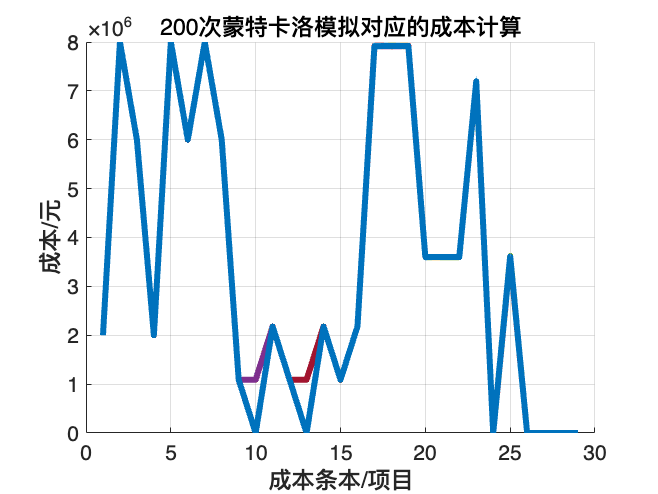

xlabel("成本条本/项目")
ylabel("成本/元")
title("200次蒙特卡洛模拟对应的成本计算")


x=1:29
for i = 1:simulate
     [income(i),each_cost(i,:)] = Pbl4eachCost(result(i,:)');
     plot(x, each_cost(i,:)/1e4, 'LineWidth', 1);

end
writematrix(result,"第四问蒙特卡洛模拟结果.txt")
writematrix(income,"第四问蒙特卡洛模拟利润")
writematrix(each_cost,"第四问蒙特卡洛模拟成本")

grid on
each_cost/1e4
var_cost =  mean(var((each_cost/1e4)))
xlabel("成本条本/项目")
ylabel("成本/元")
title("50次蒙特卡洛模拟对应的成本计算")
var(income/1e4)
plot(1:50,income/1e4)

